Opóźnienia wewnętrzne mogą powstać, gdy dodamy pętlę sprzężenia zwrotnego do systemu z opóźnieniem I/O (na wyjściu lub wyjściu), jak tu [https://www.mathworks.com/help/control/ug/closing-feedback-loops-with-time-delays.html](https://www.mathworks.com/help/control/ug/closing-feedback-loops-with-time-delays.html) :

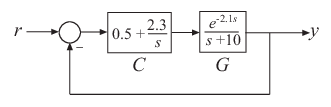

G = tf(1,[1 10], 'InputDelay' ,2.1);
C = pid(0,5,2,3);
T = feedback(C*G,1) % To jest dokładny model, nie aproksymacja,


T =
 
  A = 
           x1      x2      x3
   x1     -11  -4.167  -1.667
   x2       2       0       0
   x3       0     0.5       0
 
  B = 
       u1
   x1   2
   x2   0
   x3   0
 
  C = 
           x1      x2      x3
   y1  0.3333    1.25  0.8333
 
  D = 
       u1
   y1   0
 
  (values computed with all internal delays set to zero)

  Internal delays (seconds): 2.1 
 
Continuous-time state-space model.


                    % JAK TO JEST LICZONE ???

## `delayss()`

Służy do tworzenia systemów z opóźnieniem opisanych postacią (jest to kombinacja systemów z opóźnieniem na wejściu, wyjściu i opóźnień wewnętrznych):

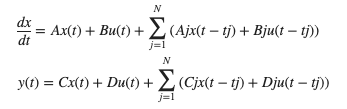

Należy zdefiniować macierz o j wierszach i elementach dla opónienia (w sekundach) oraz odpowiadających elementów dla macierzy A,B,C,D. 

Przykładowy system:

**UWAGA! **W trakcie wyświetlania macierzy A, B, C, D oprogramowanie ustawia wszystkie opóźnienia na zero (tworząc przybliżenie Padégo rzędu zerowego). To przybliżenie występuje tylko na potrzeby wyświetlania, a nie obliczeń z wykorzystaniem modelu. Gdy wyświetlenie zwraca błąd lub tylko rozmiara, to znaczy, że ustawienie opóźnienia na zero spowodowało wpadnięcie w pętlę algebraiczną (co to znaczy?).

clear all;
close all;

DelayT(1) = struct('delay',0.5,'a',0,'b',2,'c',1,'d',0);
DelayT(2) = struct('delay',1.2,'a',-1,'b',0,'c',0,'d',0);
sys = delayss(1,0,0,1,DelayT) 


sys =
 
  A = 
       x1
   x1   0
 
  B = 
       u1
   x1   2
 
  C = 
       x1
   y1   1
 
  D = 
       u1
   y1   1
 
  (values computed with all internal delays set to zero)

  Internal delays (seconds): 0.5  0.5  1.2 
 
Continuous-time state-space model.


Co można z tym robić?

Według [https://www.mathworks.com/help/control/ug/internal-delays.html](https://www.mathworks.com/help/control/ug/internal-delays.html) systemy z opóźnieniem wewnętrznym wspierane są przez funkcje:

-  generujące symulacje czasowe i częstotliwościowe (odpowiedzi?) w czasie ciągłym ponieważ nie trzeba aproksymować Pade ???

- `margin, allmargin, pole, zero, get, ssdata `ale z pewnymi ograniczeniami (patrz  cz. 2)

I NIE są wspierane przez (dopóki nie przeprowadzi się na nich aproksymacji padego):  `norm, isstable, initial, initialplot, balreal, balred, modred, rlocus, lqg, lqry, lqrd, kalman, kalmd, lqgreg, lqi, augstate`

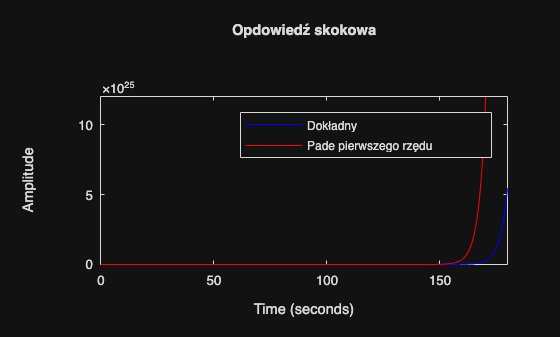

% cz. 1
sys1 = pade(sys,1); 
step(sys, "b", sys1, "r") % i inne funkcje odpowiedzi w dziedzinie czasu, poza impulse i initial
title("Opdowiedź skokowa")
legend( 'Dokładny' , 'Pade pierwszego rzędu' )

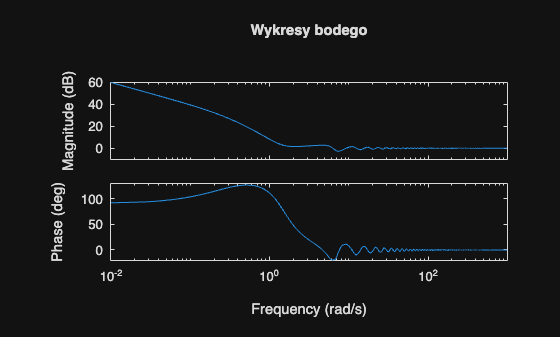


% impulse(sys)
% title("Odpowiedź impulsowa") NIE WSPIERA
% initial(sys)
% title("Odpowiedź niewymuszona") NIE WSPIERA

bode(sys) % i inne funkcje odpowiedziw  dziedzinie częstotliwości, poza norm
title("Wykresy bodego")


% norm(sys) 
% title("średnio kwadratowa odpowiedź impulsowa (?)") NIE WSPIERA

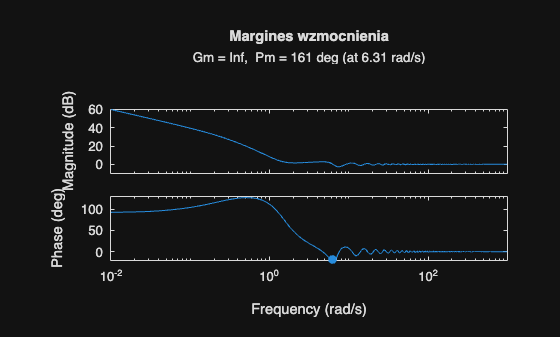

% cz. 2
% WYKORZYTUJĄ INTERPOLACJĘ (w jaki sposób, do czego?)
margin(sys)
title("Margines wzmocnienia")


allmargin(sys)

ans = struct with fields:
     GainMargin: [1×0 double]
    GMFrequency: [1×0 double]
    PhaseMargin: [160.7247 -168.9122 170.6449 -172.9823 174.1973 -174.6069 175.8122 -175.8503 176.3788 -176.8717 176.9370 -177.3159 177.4096 -177.5933 177.7476 -177.8183 178.0425 -178.1805 178.2185 -178.3214 178.3194 -178.5102 178.4879 … ] (1×50 double)
    PMFrequency: [6.3064 9.2416 12.5087 15.6522 18.8105 21.9193 25.1450 28.1750 31.4486 34.4802 37.7031 40.7994 43.9639 47.1029 50.2494 53.3756 56.5572 59.6393 62.8444 65.9283 69.1196 72.2266 75.3902 78.5353 81.6712 84.8100 87.9628 … ] (1×50 double)
    DelayMargin: [0.4448 0.3609 0.2381 0.2085 0.1616 0.1476 0.1220 0.1141 0.0979 0.0927 0.0819 0.0781 0.0704 0.0676 0.0617 0.0596 0.0549 0.0532 0.0495 0.0481 0.0450 0.0439 0.0413 0.0403 0.0382 0.0373 0.0355 0.0347 0.0331 0.0325 0.0311 … ] (1×50 double)
    DMFrequency: [6.3064 9.2416 12.5087 15.6522 18.8105 21.9193 25.1450 28.1750 31.4486 34.4802 37.7031 40.7994 43.9639 47.1029 50.2494 53.3756 56.5572 59.63

disp('Margines wzmocnienia, fazy i opóźnienia');

Margines wzmocnienia, fazy i opóźnienia



% USTAWIA OPÓŹNIENIA NA ZERO
pole(sys)

ans = 0

disp("Bieguny systemu")

Bieguny systemu


zero(sys)

ans = -2

disp("Zera systemu")

Zera systemu


ssdata(sys)

ans = 0

disp("Macierze opisu przestrzeni stanu")

Macierze opisu przestrzeni stanu


get(sys)

                A: 0
                B: 2.0000
                C: 1
                D: 1
                E: []
          Offsets: []
           Scaled: 0
        StateName: {''}
        StatePath: {''}
        StateUnit: {''}
    InternalDelay: [3×1 double]
       InputDelay: 0
      OutputDelay: 0
        InputName: {''}
        InputUnit: {''}
       InputGroup: [1×1 struct]
       OutputName: {''}
       OutputUnit: {''}
      OutputGroup: [1×1 struct]
            Notes: [0×1 string]
         UserData: []
             Name: ''
               Ts: 0
         TimeUnit: 'seconds'
     SamplingGrid: [1×1 struct]



disp("Informacje o systemie")

Informacje o systemie


## Model opóźnineń czasowych, `getDelayModel()`

reprezentowany jest za pomocą 

- zwykłego opisu w przestrzeni stanów H(s) z rozszerzonym zestawem wejść,

- zestaw opóźnień wewnętrznych.

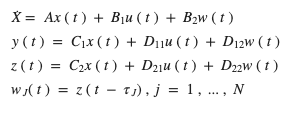                                      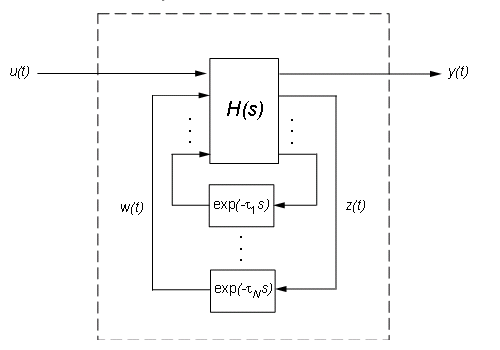

Aby uzyskać model opóźnień czasowych w postaci modelu przestrzeni stanów bez opóźnień i wektora opóźnień stosuje się funkcję `getDelayModel() `(funkcja odwrotna to` setDelayModel()`)

sys


sys =
 
  A = 
       x1
   x1   0
 
  B = 
       u1
   x1   2
 
  C = 
       x1
   y1   1
 
  D = 
       u1
   y1   1
 
  (values computed with all internal delays set to zero)

  Internal delays (seconds): 0.5  0.5  1.2 
 
Continuous-time state-space model.


[H, tau] = getDelayModel(sys) % działa dla typów ss, sprass, mechss


H =
 
  A = 
       x1
   x1   1
 
  B = 
           ?     w1     w2     w3
   x1      0  1.414      0      1
 
  C = 
       x1
   ?    0
   z1   0
   z2  -1
   z3  -1
 
  D = 
           ?     w1     w2     w3
   ?       1      0     -1      0
   z1  1.414      0      0      0
   z2      0      0      0      0
   z3      0      0      0      0
 
Continuous-time state-space model.


tau =     0.5000
    0.5000
    1.2000


## Analiza systemów z opóżnieniem

[https://www.mathworks.com/help/control/ug/analyzing-control-systems-with-delays.html](https://www.mathworks.com/help/control/ug/analyzing-control-systems-with-delays.html)

- odpowiedzi czasowe i czestotliwościowe

- aproksymacja padego

- analiza wraćliwości *dodać

- dyskretyzacja *dodać

% tu dodać kod kiedyś

## Ciekawe właściwości systemów z opóźnieniem

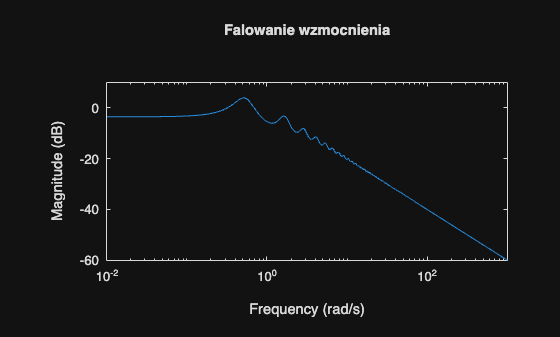

s = tf('s'); 
G = exp(-5*s)/(s+1);
T = feedback(G,.5);
bodemag(T)
title("Falowanie wzmocnienia")

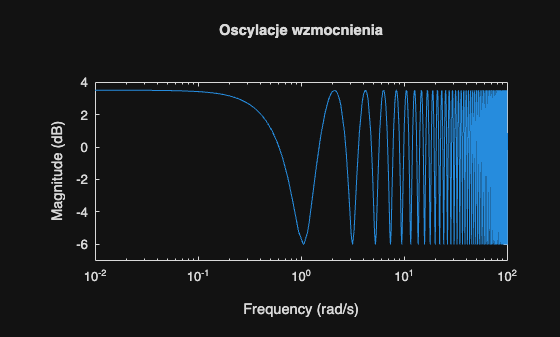


G = 1 + 0.5 * exp(-3*s);
bodemag(G)
title("Oscylacje wzmocnienia")

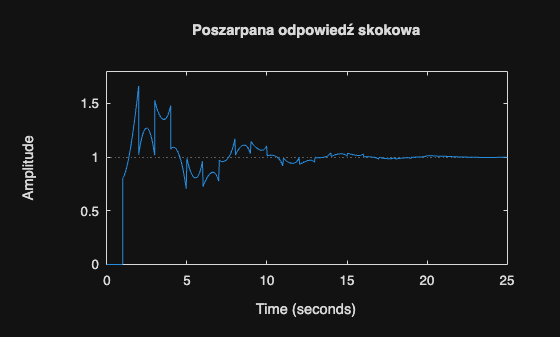


G = exp(-s) * (0.8*s^2+s+2)/(s^2+s);
T = feedback(G,1);
step(T)
title("Poszarpana odpowiedź skokowa")

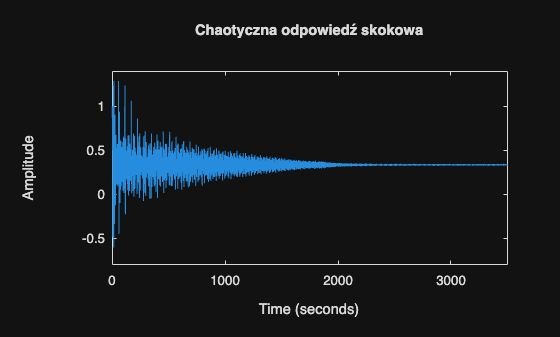


G = 1/(s+1) + exp(-4*s);
T = feedback(1,G);
step(T)
title("Chaotyczna odpowiedź skokowa")

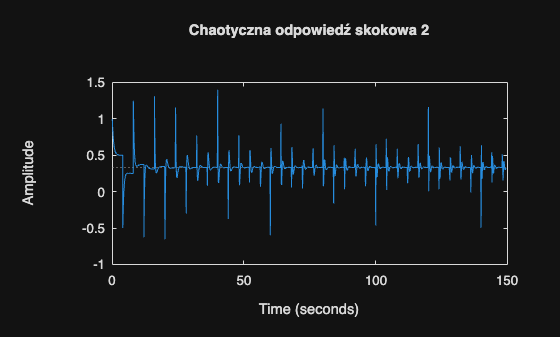


G = 1/(s+1) + exp(-4*s);
T = feedback(1,G);
stepplot(T,150)
title("Chaotyczna odpowiedź skokowa 2")